# Bisection Method 

The bisection method is used to find the roots of polynomial[ ](https://byjus.com/maths/roots-of-polynomials/)equation. It separates the interval and subdivides the interval in which the root of the equation lies. The principle behind this method is the intermediate theorem for continuous functions. It works by narrowing the gap between the positive and negative intervals until it closes in on the correct answer. This method narrows the gap by taking the average of the positive and negative intervals. It is a simple method and it is relatively slow. The bisection method is also known as **interval halving** method, **root-finding **method, **binary search** method or **dichotomy **method.

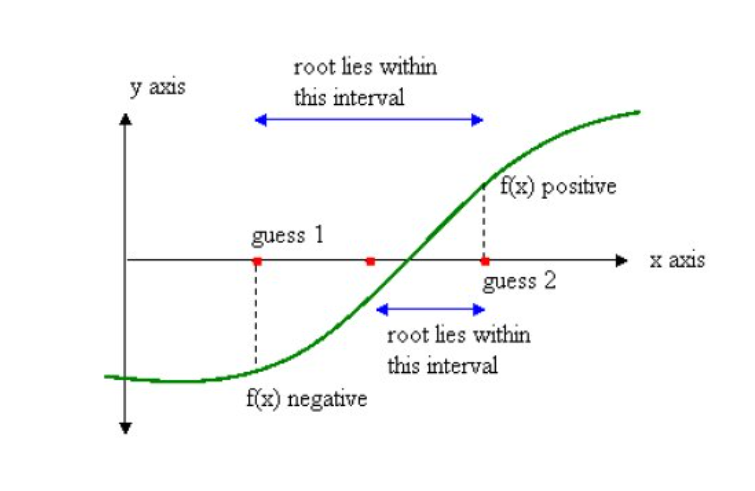

### Converging Towards Root:

The Bisection method is based on the Bolzano’s theorem for continuous functions (corollary of intermediate value theorem)

***Theorem (Bolzano) : If the function f(x) is continuous in [a, b] and f(a)f(b) < 0 (i.e. f(x) has opposite signs at a and b)then a value c ∈ (a, b) exists such that f(c) = 0***

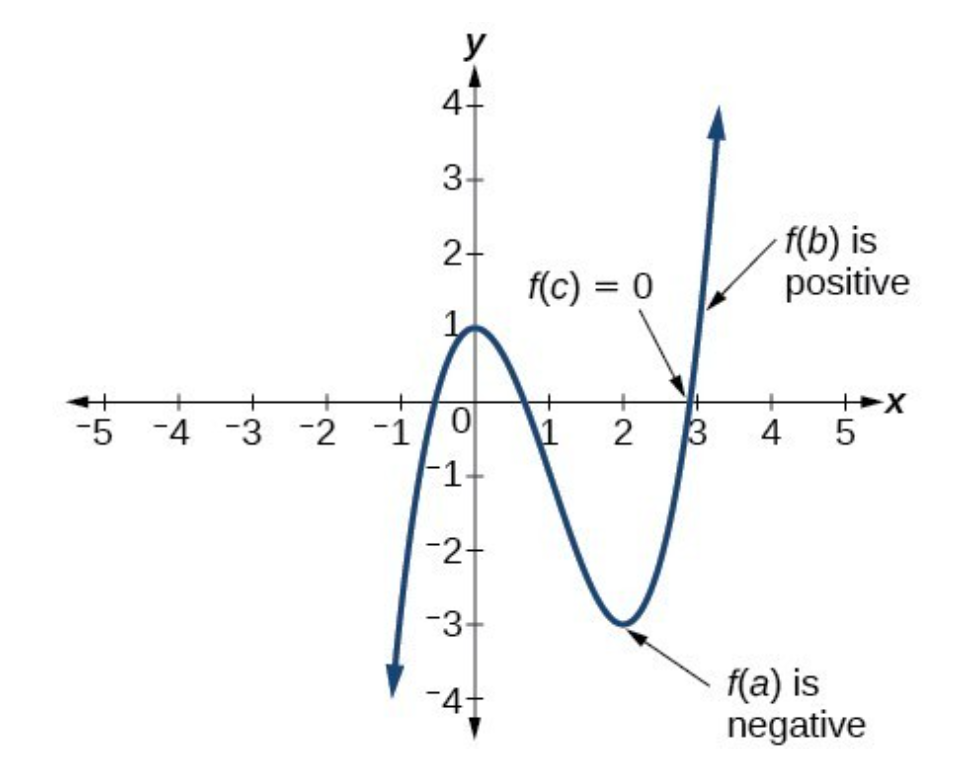

The bisection method is an approximation method to find the roots of the given equation by repeatedly dividing the interval. This method will divide the interval until the resulting interval is found, which is extremely small.

## **Bisection Method Algorithm:**

For any continuous function f(x)

- Find two points, say **a** and **b** such that **a** < **b** and **f(a)*** **f(b)** < 0

- Find the midpoint of a and b, say "$x_r$".

- $x_r$ is the root of the given function if **f(**$x_r$**) = 0**; else follow the next step

- Divide the interval **[a, b]** – If **f(**$x_r$**)*f(a) <0**, there exist a root between $x_r$ and a .so $x_r$ will be our new b.Else if **f(**$x_r$**) *f (b) < 0**, there exist a root between $x_r$ and b ,so $x_r$ will be our new a.

- Repeat above three steps until we achieve our required accuracy of root.

### **Step 1 : Defining the Function **

First step of bisection method is to define the function and it's lower bound and upper bound which is **a** and **b. **We have to remember that the the functional value of point **a** and **b** must have to be opposite sign.For ensuring the accuracy of the root, we have to define the accuracy(**accuracy**) .

Here we will take function as input from user which will be treated as a string and stored into  **f_input** variable.Using inline function (ignoring warning )  we have turned it into a vector which can be calculated by Matlab.

Here we have defined accuracy as approximate relative error which can be representated as 

### 
$$\textrm{accuracy}=|\frac{x_r^{\textrm{new}} -x_r^{\textrm{old}} }{x_r^{\textrm{old}} }|$$


For simplification of our calculation we didnot converted the accuracy into % .So if we want 1% accuracy here the value of accuracy will be 0.001

f_input = input("Enter f(x) = ","s");           %Function of variable x
f = inline(f_input);                            %using inline function
a = input ( "Value of a =");
b = input ( "Value of b =");
accuracy = input ( "Value of required accuracy  =");

### **Step 2 : Checking Functional Value at point a and b**

In this step we will use **if** statement to check that is the input value satisfies the condition of bisection method which is the multiplication of  functional value at point a and b will be smaller than 0.If the multiple of functional value at boundary point denies the required condition we will print a message and use **return** statement to stop executing rest of the matlab script.

Why we will not check that, Is the  user defined roots as one of the boundary values ?  

if f(a) * f(b) > 0 
    fprintf("No roots exist within the given interval \n");
    return
end 

if (f(a) == 0 || f(b) == 0 )
    fprintf("Boundary value is one of the roots\n")
    return 
end


### **Step 3 : Initialize the values **

First we have to inititalize some required values.To start counting our number of interation, we assigned  i= 0 , and we have initialized our first $x_r^{\textrm{old}} =a\;$

i = 0;
xr_old = a ;

### **Step 4 : Let's start iteration **

- For iteration process we will use while loop as our iteration will continue untill we achieve our required accuracy.

- Next accepted root according to biscection is $x_r =\frac{a+b}{2}$ 

-  If f($x_r$) *f (b) < 0, there exist a root between $x_r$ and b ,so $x_r$ will be our new a.Else , f($x_r$)*f(a) <0,  so there exist a root between $x_r$ and a .so $x_r$ will be our new b.

- As first iteration is completed we will increase the value of **i** by one which is our number of iteration.

- As the value of our **a **or **b**  is changed, now we will calculate our next $x_r$ value $x_r =\frac{a+b}{2}$ and assign our previous $x_r$ value to $x_r^{\textrm{old}}$.

- As we want to print our iteration result as table, so firstly we have printed heading of the table. Then we have printed all other values of current iteration  

while abs ((xr_old-xr)/xr) > accuracy
    xr = (a+b)/2;
    if (f(xr)*f(b)<0)
        a =xr;
    else 
        b=xr;
    end
    i=i+1;
    xr_old = xr;
    xr= (a+b)/2;
    if i == 1
        fprintf("Iteration \t\t a \t\t b \t\t Xr");
    end
 
    fprintf('\n %d \t \t %f\t %f\t %f', i, a,b,xr);
end

### **Step 6 : Final Result **

After completing the iteration we will print our final result which is the latest $x_r$ Value .The data type of our result is double ,so we used %f as format specifier.

fprintf("\n \t Root of equation is %f",xr);